Define the continuous-time transfer function

s = tf('s');
G_s = 1 / (s + 1) 

G_s =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.
Model Properties


Define different sampling times

Ts_values = [0.1, 0.5, 1, 2]; 

Plotting

figure;
hold on;


Loop over different Ts values and calculate the discrete transfer function

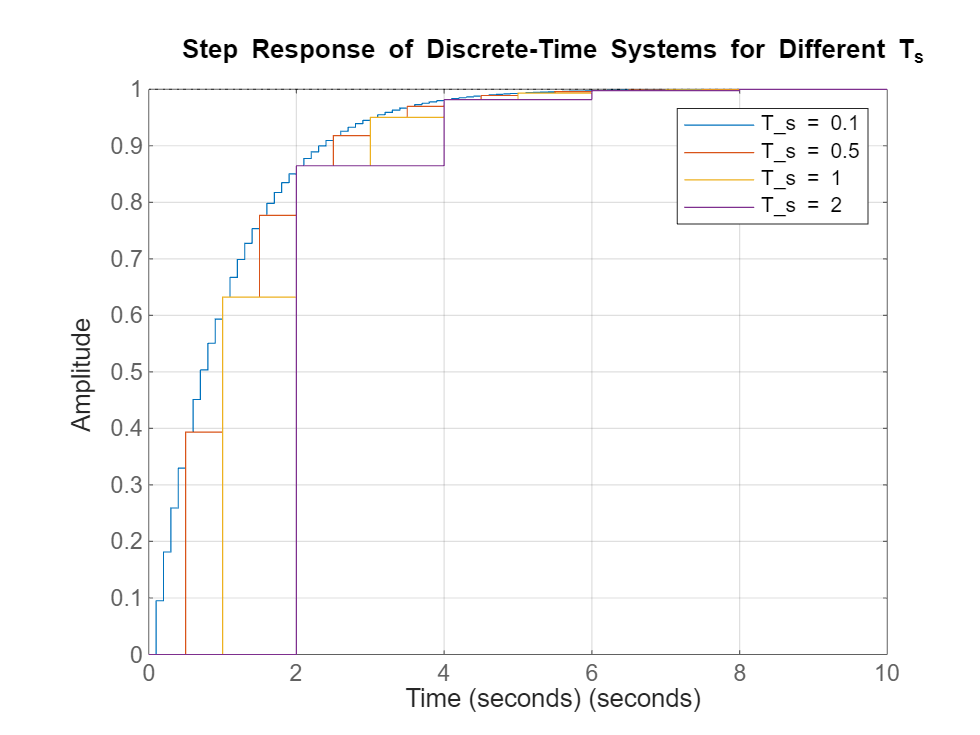

for i = 1:length(Ts_values)
    Ts = Ts_values(i); % Current sampling period
    % Discretize the transfer function using zero-order hold (ZOH)
    G_z = c2d(G_s, Ts, 'zoh');
    
    % Plot the step response
    step(G_z, 10);
    % 
    % disp(['Discrete transfer function for Ts = ', num2str(Ts)]);
    % disp(G_z);
end

% plot details
legend(arrayfun(@(x) ['T_s = ' num2str(x)], Ts_values, 'UniformOutput', false));
title('Step Response of Discrete-Time Systems for Different T_s');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;
hold off;